## **CU Anschutz-Medtronic Percieve Collaboration**

The purpose of this report is to illustarte key findings from the data acquisition and early analysis portion of this study. 

This section loads in variables that are useful to the other fuctions. Further, this section helps to process files coming from a patient with either single or double batteries, enhancing the modularity of the code. 

clear
cd('C:\Users\sydne\Documents\github\perceive')
jsonFiles = 'Report_Json_Session_Report_20210819T134933.json';
%For this particular patient, this file encodes the RIGHT side 
js = jsondecode(fileread(jsonFiles));
cd('C:\Users\sydne\Documents\github\perceive') 

channels = unique({js.LfpMontageTimeDomain.Channel}, 'stable');
leng = numel({js.LfpMontageTimeDomain.Channel});
startindex = 1; %all trials were fine so start at 1 
sides = {'LEFT', 'RIGHT'};
if any((contains(channels, sides{1}))) && any((contains(channels, sides{2}))) 
        doubleBattery = false; 
        %json has both left and right data 
        channelsLeft = channels(contains(channels, sides{1}));
        channelsRight = channels(contains(channels, sides{2}));
    else 
        doubleBattery = true; 
end 


#### Frequency vs power plot for all contact pairs

After data is collected from Brainsense, the three trials are averaged and presented as a single line. All six pairs are represented. Smoothing has maintained the shape of the curve but altered the power, thus not always matching the maximum power reported. 

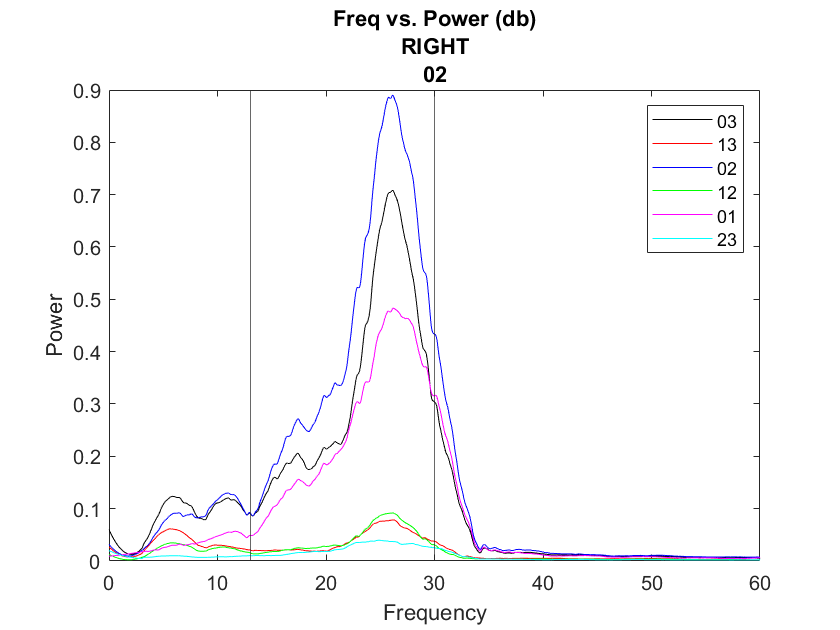

 colors = 'krbgmc';
    maxValues = zeros(length(channels), 1);
    for c=1:length(channels)
        maxValues(c) = tempAvgPlot(7, leng, js, channels{c}, colors(c));
        hold on;
    end 
    
    [M, I] = max(maxValues);
    highestBeta = channels{I};
    
    %add all the plot info
    
    xline(13);
    xline(30);
    
   legendChan = cell(6);
        oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'}; 
        newchar = {''}; 
        oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'}; 
        newnum = {'0', '1', '2', '3'};
        for b = 1:length(channels)
            legendChan{b} = replace(channels{b}, oldchar, newchar);
            legendChan{b} = replace(legendChan{b}, oldnum, newnum);
        end
        legend(legendChan{1}, legendChan{2}, legendChan{3}, legendChan{4}, legendChan{5}, legendChan{6}) 
        
    title(["Freq vs. Power (db)", "RIGHT", legendChan{I}])
    xlim([0 60])
    xlabel("Frequency")
    ylabel("Power")

disp(['The highest beta comes from contact pair', legendChan{I}])

The highest beta comes from contact pair02


#### Compare beta between contacts with standard deviation 

The average between all three trials is taken. Then, the max is found within the beta region and plotted. Standard devation is of the average of the three trails and within the beta region. 

    disp("Beta bar chart summary for the RIGHT")

Beta bar chart summary for the RIGHT


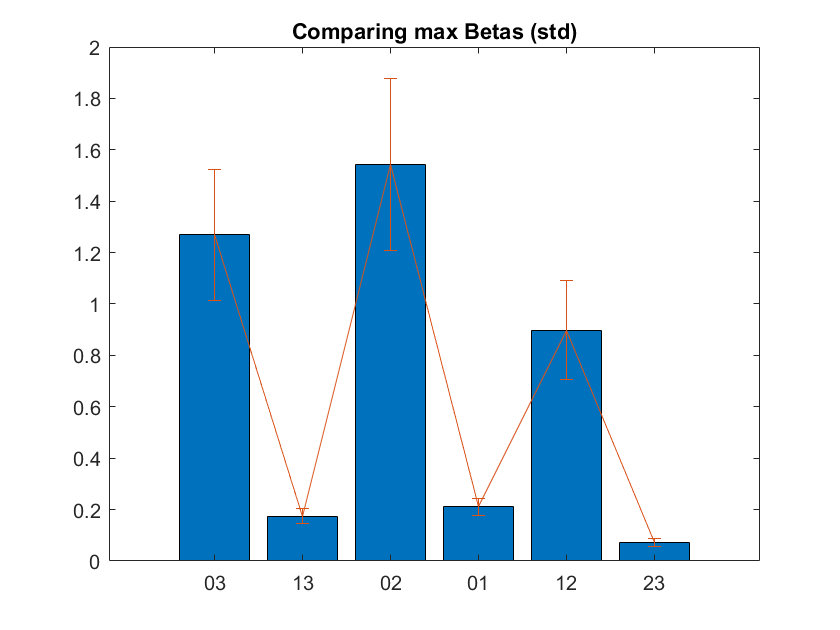

    compareBetaBarChart(startindex, leng, js, channels);

    figure;

#### All frequency spectrum for max beta contacts

For the contact pair that is determined to produce the most beta, full spectrum analysis was performed. Delta is defined as between 0-4.99Hz, theta is between 5-8.99Hz, alpha is 9-11.99Hz, beta is 12-33.99Hz, and gamma is from 34-100Hz. 

disp("All frequency bar chart summary for the RIGHT")

All frequency bar chart summary for the RIGHT


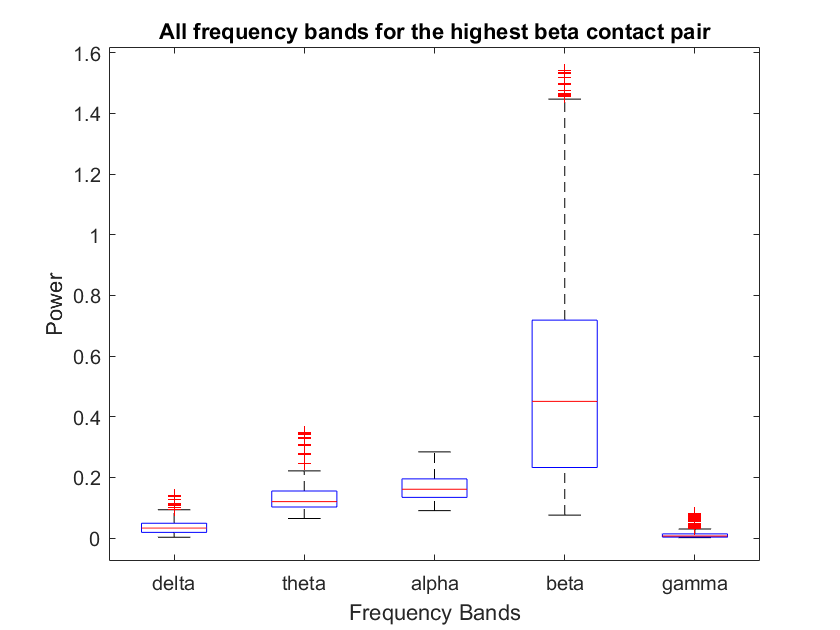

allFreqBarChart(startindex, leng, js, highestBeta)

#### Mean and Standard Deviation for each Trial

In descending order of beta activity, the means and stds of each contact pair is displayed. Each contact pair has the mean and std for each trial listed. These values come only from the beta region. A more concise visualization is below. Data is for the left and right. 

   %% 
   disp("Table trial summary for the RIGHT")

Table trial summary for the RIGHT


   maxMeanBetaAllRuns(startindex, js, leng, channels);

ans = 6×7 table
              Var1              Mean R1     Mean R2     Mean R3      STD R1      STD R2      STD R3 
    ________________________    ________    ________    ________    ________    ________    ________

    {'ZERO_AND_TWO_RIGHT'  }     0.36268     0.62412     0.71298     0.25238     0.47916     0.53289
    {'ZERO_AND_THREE_RIGHT'}      0.2598     0.46934     0.53291     0.18278      0.3688     0.41371
    {'ZERO_AND_ONE_RIGHT'  }     0.21887     0.36651     0.41598     0.14706     0.27352     0.29837
    {'ONE_AND_THREE_RIGHT' }    0.037396    0.059086     0.05947    0.025254    0.043315    0.046699
    {'ONE_AND_TWO_RIGHT'   }    0.035686     0.05956    0.068176    0.021931     0.04662    0.054767
    {'TWO_AND_THREE_RIGHT' }    0.0295

#### Visualization of Trial Variability

For each contact, all three trials are plotted together to illustrate the variability from run-to-run for each Brainsense survey. Data has undergone smoothing that maintains the shape but not nessicarily the values. More granular information is in the table above. 

   disp("Graph trial summary for the RIGHT")

Graph trial summary for the RIGHT


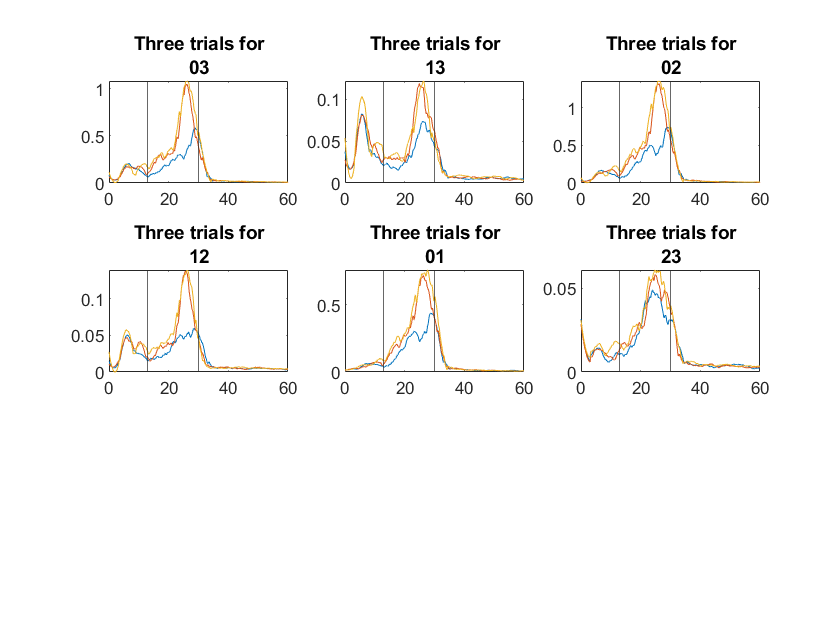

   graphEachTrials(startindex, js, leng, channels);